clearvars -except data results v_results all_fiji_data

## Analysis of segmented data

### Description of data obtained from computer vision code

The computer vision code detects cells present in a timepoint from the images obtained through epi-flourescent microscopy, returning a table of properties for every detected cell in a side channel, such as it's x,y coordinates; timepoint; area; and pixel intensities. The list of properties generated are displayed below, and a table of values from a side channel. Each row represents the detection of a cell.

The description of these properties can be found here: [https://imagej.nih.gov/ij/docs/menus/analyze.html](https://imagej.nih.gov/ij/docs/menus/analyze.html)

load names.mat
example_data_names = horzcat("RFP_"+names,"YFP_"+names(22),"YFP_"+names(27))

example_data_names = 1×37 string array
    "RFP_N"    "RFP_Area"    "RFP_Mean"    "RFP_StdDev"    "RFP_Mode"    "RFP_Min"    "RFP_Max"    "RFP_X"    "RFP_Y"    "RFP_XM"    "RFP_YM"    "RFP_Perim."    "RFP_BX"    "RFP_BY"    "RFP_Width"    "RFP_Height"    "RFP_Major"    "RFP_Minor"    "RFP_Angle"    "RFP_Circ."    "RFP_Feret"    "RFP_IntDen"    "RFP_Median"    "RFP_Skew"    "RFP_Kurt"    "RFP_%Area"    "RFP_RawIntDen"    "RFP_Slice"    "RFP_FeretX"    "RFP_FeretY"    "RFP_FeretAngle"    "RFP_MinFeret"    "RFP_AR"    "RFP_Round"    "RFP_Solidity"    "YFP_IntDen"    "YFP_RawIntDen"


example_fiji = array2table(all_fiji_data{1,1},"VariableNames",example_data_names)

example_fiji = 13050×37 table
    RFP_N    RFP_Area    RFP_Mean    RFP_StdDev    RFP_Mode    RFP_Min    RFP_Max    RFP_X     RFP_Y     RFP_XM    RFP_YM    RFP_Perim.    RFP_BX    RFP_BY    RFP_Width    RFP_Height    RFP_Major    RFP_Minor    RFP_Angle    RFP_Circ.    RFP_Feret    RFP_IntDen    RFP_Median    RFP_Skew    RFP_Kurt    RFP_%Area    RFP_RawIntDen    RFP_Slice    RFP_FeretX    RFP_FeretY    RFP_FeretAngle    RFP_MinFeret    RFP_AR

### Detecting Division Events and cell lifetimes

First, mother cells are detected by sorting the data tables (obtained from the computer vision code described above) by the y coordinates of detected cells and timepoints. The cells depest in the side trench for each timepoint are the mother cells. After seperating the data for mother cells, their division events are detected by analysing the log area of mother cells over time, as displayed in the plot below.

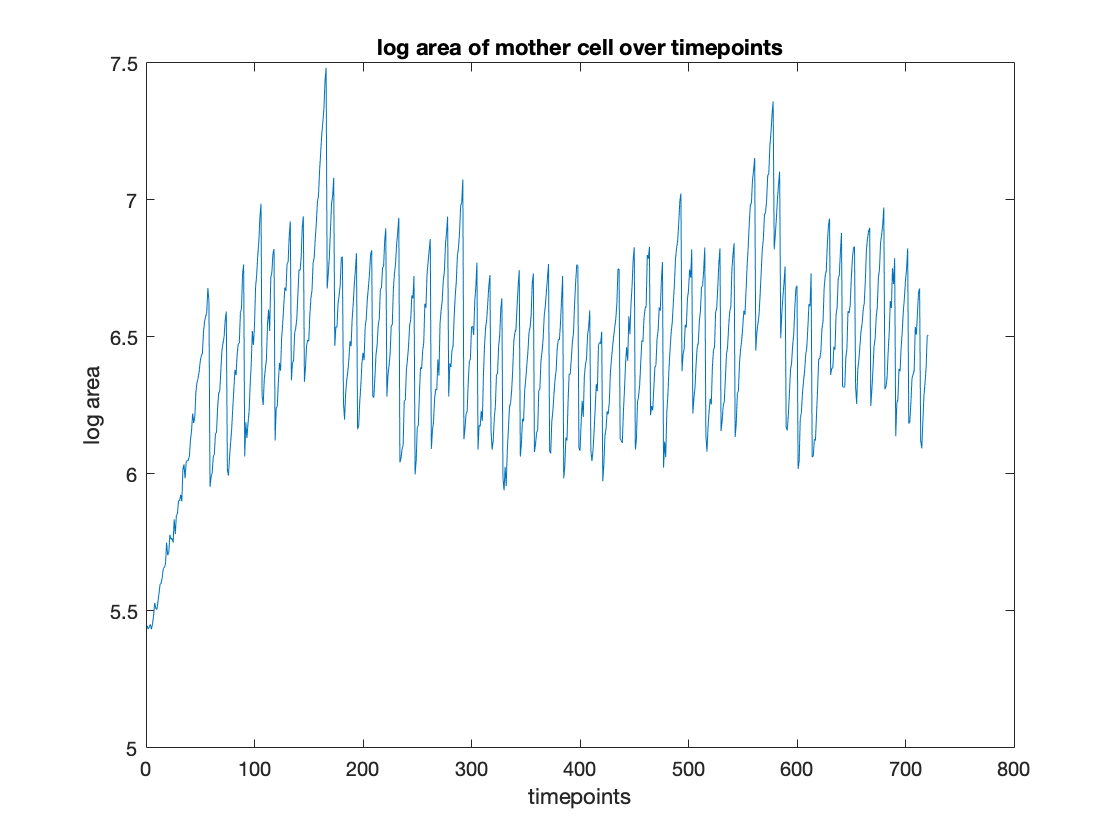

test_cell = log(data(1,:,2));
plot(test_cell)
title("log area of mother cell over timepoints")
ylabel("log area")
xlabel("timepoints")

Looking closer at divisions, it is evident that cell area follows the stereotypcial sawtooth curve for cell division.

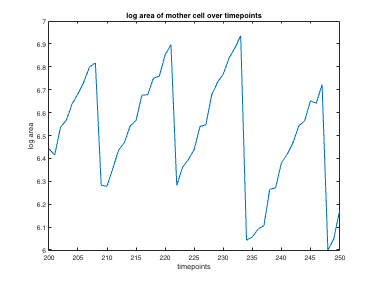

plot(test_cell)
title("log area of mother cell over timepoints")
ylabel("log area")
xlabel("timepoints")
xlim([200 250])

To detect these divison events, the forward difference is taken. Below is the negative of the forward difference of the above log area plot. The peaks are associated with cell division events which can be detected easily using peak finding algorithms.

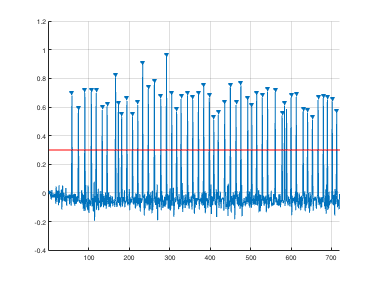

clf
hold on 
findpeaks(-diff(test_cell),'MinPeakDistance',5,'MinPeakProminence',0.5)
plot([0 721],[0.3,0.3],'r')
hold off

The data for timepoints in between these detected division events are associated with a cell lifetime, defined as a cell that exists between a birth and death event assuming all cells have a unique identity that is not retained after a division event. The growth rate for a lifetime is calculated by finding the linear fit of the log area values for timepoints within the lifetime, and the mean of the median RFP and YFP intensity for those timepoints are also calculated and stored for all mother cell lifetimes in all side channels.

### Identifying errors in division detection

The steps upstream of detecting division events and cell lifetimes are error prone. The computer vision algorithm, altough rather accurate for this experiment (see suplimentary powerpoint) may on occasion miss segment two cells as one or not detect a cell at all. Division events themselves may be abnormal and not comply the thresholding procedures described above. to analysing cell lifetimes, those arrising from errors in these two steps must first be eliminated.

The detected lifetimes are filtered according to the $R^2
$ value between the log area points and the linear fit obtained. Lifetimes with an $R^2
$ value lower than 0.9 are eliminated. Additionally properites of E Coli lifetimes known a priori are also used to eliminate erroneous lifetimes. From previous studies E Coli has been shown to not divide faster than 20 minutes and rarely taking longer than 60 minutes in rich media as used in this experiment. Applying these constraints enables robust detection of cell lifetimes.

The bellow plots indicate the detected lifetimes which will be kept as green points, those which will be discarded in red.

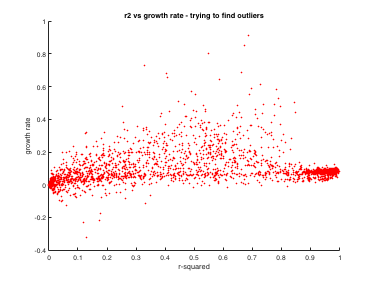

figure
hold on
scatter(v_results.v_r2(~v_results.v_keep),v_results.v_growth_rate(~v_results.v_keep),5,'filled','r')
scatter(v_results.v_r2(v_results.v_keep),v_results.v_growth_rate(v_results.v_keep),5,'filled','g')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")
hold off

Most outliers can be removed by limiting $R^2
$ to not include perfect fits, most likely due to a limited number of overvations. Since we are excluding the first and last point observed for a lifetime, up to 4 observations will lead to a perfect fit (2 points needed for linear fit). 

These points are most likely miss segmentations. The sampling rate for this experiment is 2 minutes - so 4 observed points for a cell-lifetime will relate to at most a 12 minute division time - which has never been observed in E Coli, even for strains optimized to have a fast division time(cite). In comparision here we are expressing either flouresent or also β-lactamase - our prior assumption is cell dvision times will not be lower than the fastest divison times of the WT strain in ideal conditions.

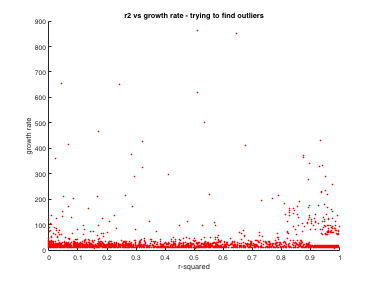

figure
hold on
scatter(v_results.v_r2(~v_results.v_keep),v_results.v_division_time(~v_results.v_keep),5,'filled','r')
scatter(v_results.v_r2(v_results.v_keep),v_results.v_division_time(v_results.v_keep),5,'filled','g')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")
hold off

The number of points retained when removing poor $R^2
$ values are:

percent_keeping = sum(v_results.v_keep)/length(v_results.v_keep)

percent_keeping = 0.6553

The effects of removing erroneous lifetime segmentations can be observed by comaring the below plots, one of a trench experiencing regular cell growth and another where the cell has died early in the experiment. Erroneous lifetimes are depicted with the linear fit plotted in red, while those accepted are plotted in green.

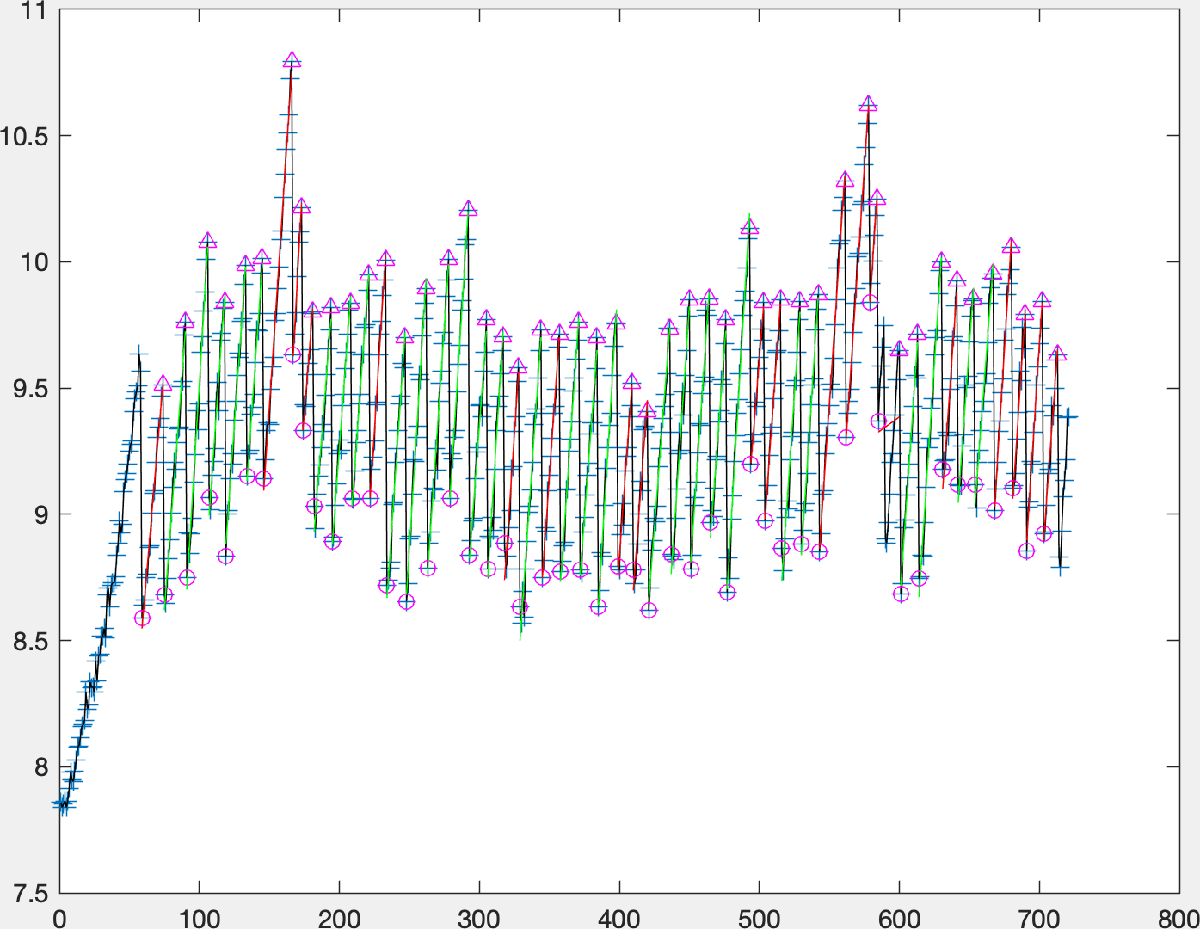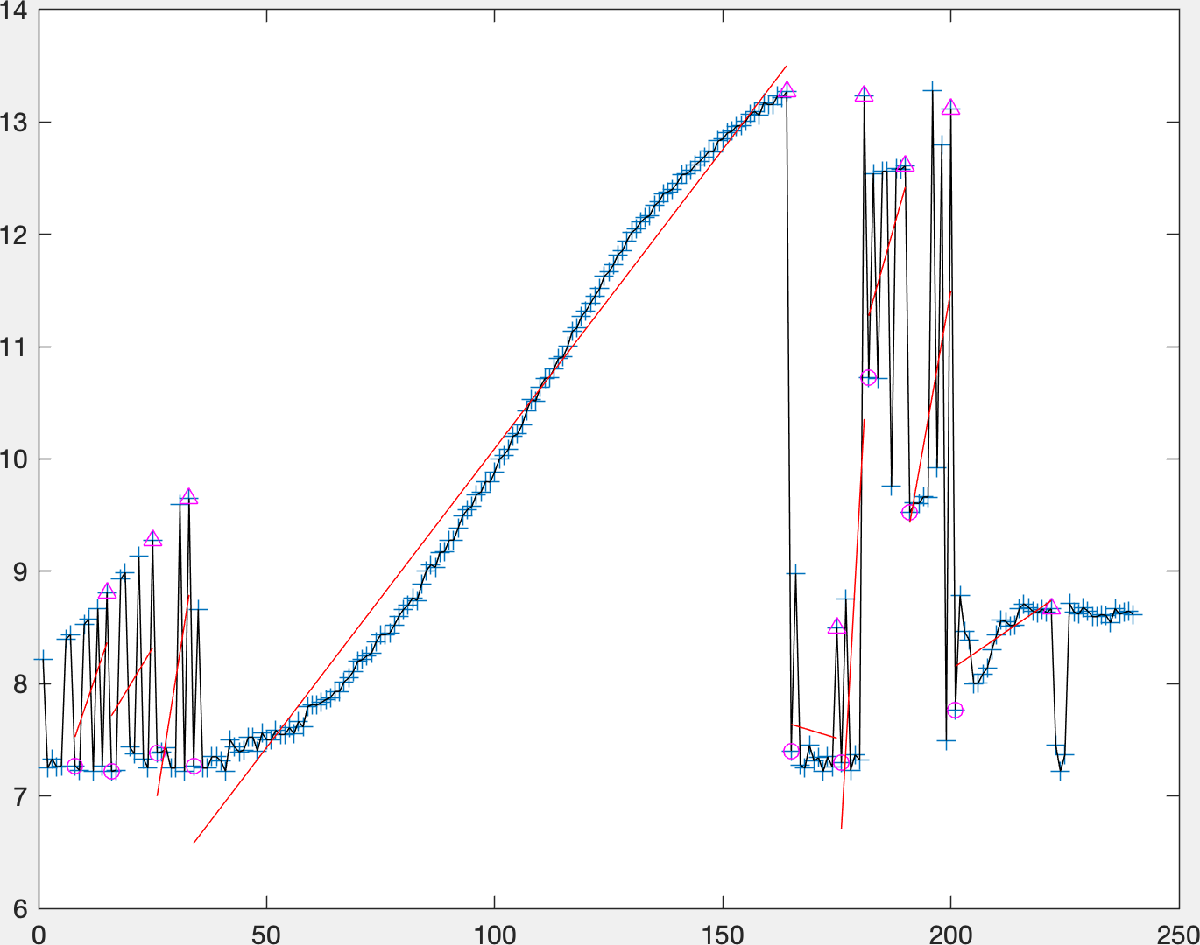

### Finding threshold to seperate populations

Looking at the retained values, we can segment the population in two - those expressing YFP and those that are not.

The cells expressing YFP must contain the plasmid ampR:YFP. The cells not expressing YFP either didn't contain the plasmid initially or lost them. By obeserving the histogram of YFP intentsity we can segment these two populations, a value of 250 seems to be a good threshold as demonstrated in the plot below. The light gray area of the histogram depicts cells classed as not containing the ampR:YFP plasmid, while the dark gray section depicts cells classed as containing the plasmid.

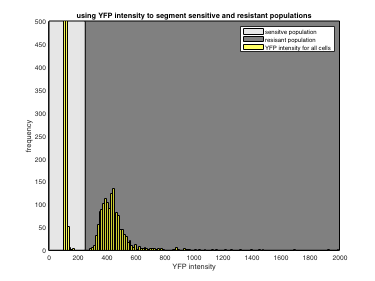

clf

threshold = 250; %threshold to segment populations

%size of graph
ymax = 500;
xmax = 2000;

hold on
patch([threshold,0,0,threshold],[0,0,ymax,ymax],0.9*ones(1,3))
patch([xmax,threshold,threshold,xmax],[0,0,ymax,ymax],0.5*ones(1,3))
histogram(v_results.v_yfp(v_results.v_keep),1000,'FaceColor','yellow')
ylim([0 ymax])
xlim([0 xmax])
xlabel("YFP intensity")
ylabel("frequency")
legend("sensitve population","resisant population","YFP intensity for all cells")
title("using YFP intensity to segment sensitive and resistant populations")
sensitive_id = v_results.v_keep & (v_results.v_yfp<threshold);
resistant_id = v_results.v_keep & (v_results.v_yfp>=threshold);
number_sensitive_lifetimes = sum(sensitive_id);
number_resistant_lifetimes = sum(resistant_id);
hold off

### Population distribution of all observed mother cell lifetimes in experiment

The below bar plot indicates the distribution of lifetimes ascriped to cells containing plasmid (reisistant) and those lacking the plasmid (sensitive) according to the above thresholding proccedure to segment the populations. The growth rate of sensitive cells is expected to be faster due to the lower fitness cost of expressing and replicating the plasmid, hence sensitive cells are expected to divide more frequently that resistant cells and hence exhibit more lifetimes, however there may also be a bias in the initially loaded cells.

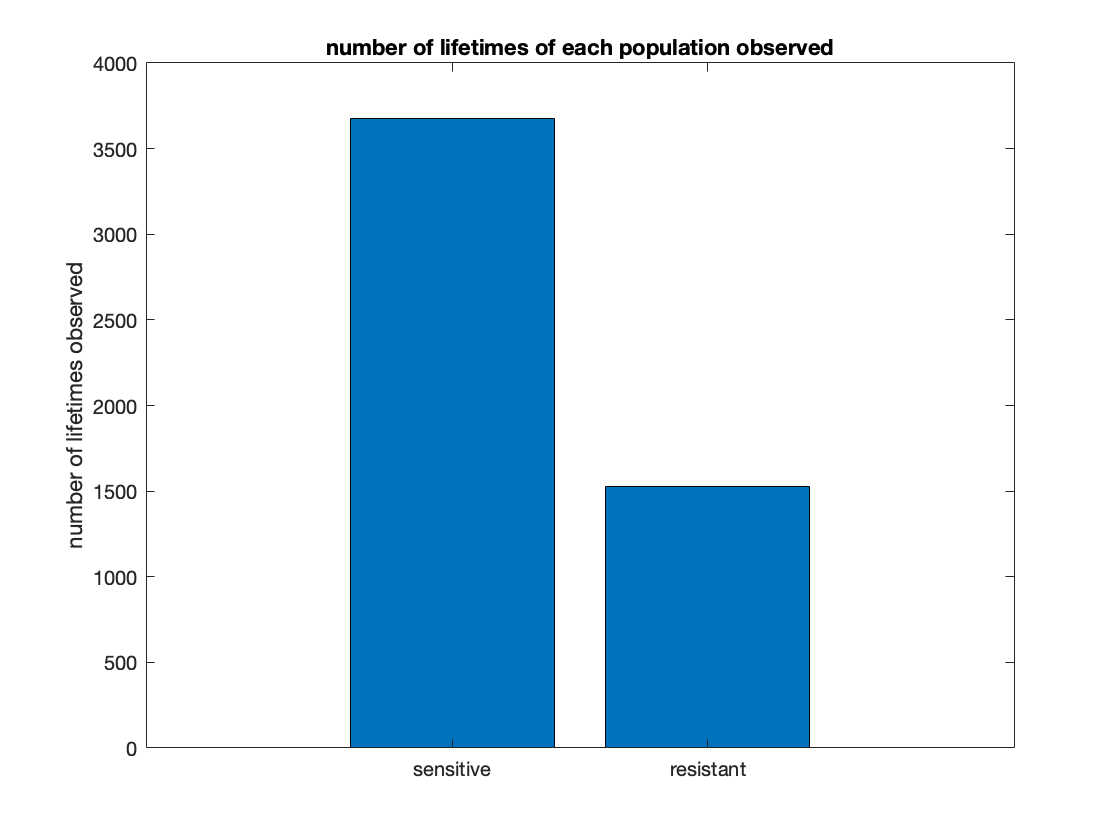

bar([number_sensitive_lifetimes,number_resistant_lifetimes]);
%xlabel(["sensitive","resistant"])
set(gca,'xticklabel',["sensitive","resistant"])
ylabel("number of lifetimes observed")
title("number of lifetimes of each population observed")

To elucidate this further, the fraction of cells that are sensitive according to the threshold classification is plotted over all timepoints. The below plot depicts a rapid rise and plateu to a fraction of 0.7. This initial rise is probably due to the fact that cells have been in stationary phase for an extended period of time, and then begin to wake up and enter exponential phase during the experiment. Cells in exponential phase will be expressing floursencents in higher number than those in stationary phase, so the thresholding shouldn't be kept constant as done above, but rather vary with time. ***

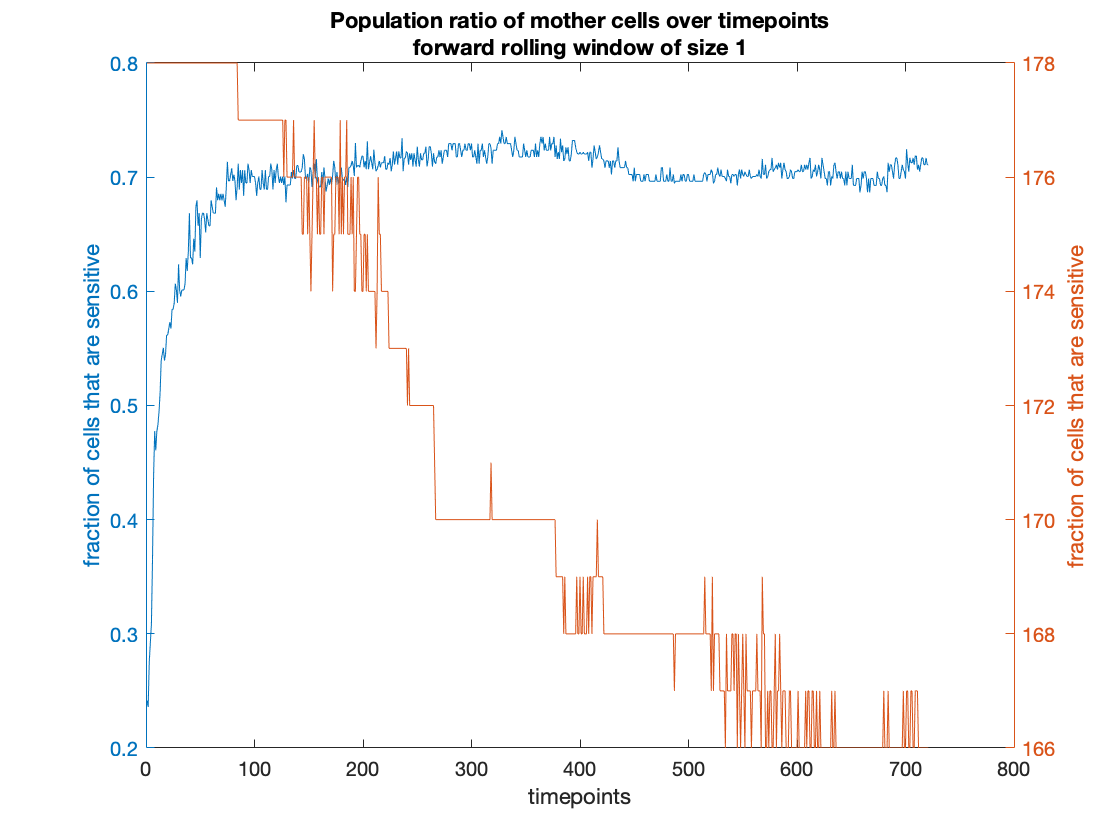

frac_sens = nan(1,size(data,2));
num_cells_at_t = nan(1,size(data,2));
length_window = 1;
for t=length_window:size(data,2)
    cells_at_t = nanmean(data(:,t-length_window+1:t,36),2);
    cells_at_t=(cells_at_t(~isnan(cells_at_t)));
    sensit = cells_at_t<threshold;
    num_cells_at_t(1,t) = length(cells_at_t);
    frac_sens(1,t) = sum(sensit)/num_cells_at_t(1,t);
end
clf
yyaxis left
plot(frac_sens)
ylabel('fraction of cells that are sensitive')
yyaxis right
plot(num_cells_at_t)
ylabel('Number of lifetimes detected')
xlabel('timepoints')
ylabel('fraction of cells that are sensitive')
title(["Population ratio of mother cells over timepoints","forward rolling window of size "+length_window])

Note that the number of lifetimes detected at each timepoint remains relatively constant, hence the number of growing mother cells remains relatively constant throughout the experiment.

When inspecting the fraction of sensitive cells out of all cells visible in the trenches the same graph appears. However, the total number of cells decreases dramatically in accordance with leaving stationary phase. This is most likely due to the fact that cells in stationary phase are shorter, and hence more cells are in the trenches initially. Fewer cells will fit into the fixed length of the mother machine side trenches during exponential phase.

all_data = [];
frac = [];

for i = 1:20
    for j = 1:9
        d = all_fiji_data{i,j};
        if(size(d,1)~=0)
            all_data = [all_data; d(:,[28,36])];
        end
    end
end

pop_dist = zeros(1,721);
total = zeros(1,721);
for t=1:721
    dist = all_data(all_data(:,1)==t,2)<threshold;
    pop_dist(1,t) = sum(dist)/length(dist);
    total(1,t) = length(dist);
end

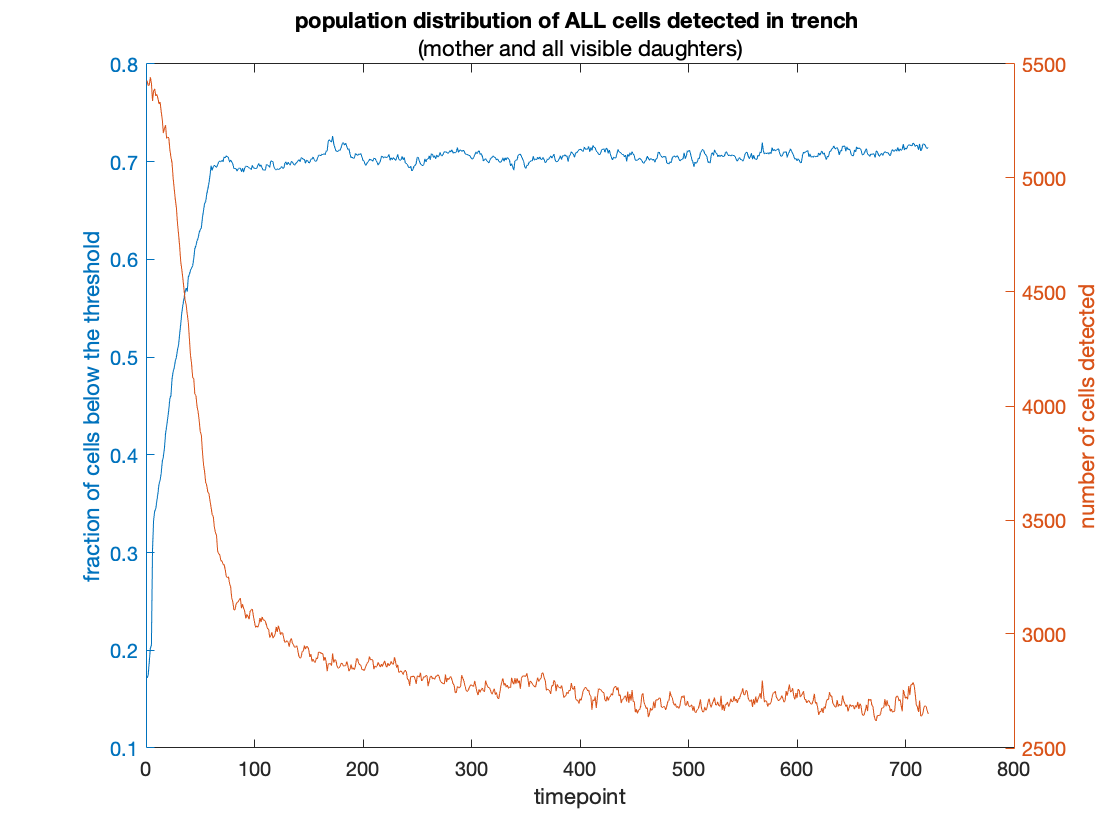

clf
title("population distribution of ALL cells detected in trench ", ...
    "(mother and all visible daughters)")
yyaxis left
plot(pop_dist)
xlabel("timepoint")
ylabel("fraction of cells below the threshold")
yyaxis right
plot(total)
ylabel("number of cells detected")

### Growth rate

Analysing these lifetime distributions segmented between the two populations enables the analysis of the affects caused by replicating and expressing the plasmid facilitating resistance. Growth rate is a key property of fitness, if a cell can grow faster it will be fitter and even a slight change in growth rate has a significant effect since cells grow exponentially. The distributions below demonstrate the difference in growth rate between the sensitive and resistant populations. The resistant population has a slower growth rate due to the metabolic burden inflicted by containing the plasmid. 

***note this growth rate is of change in log(area of pixel)/cell divisiion time - need to correct to be in m^2

Looking at the growth rate distributions

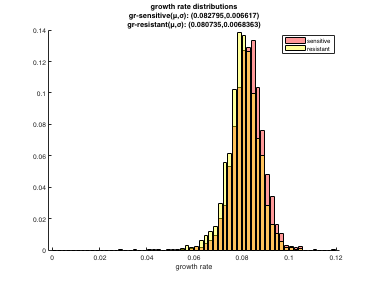

growth_rate_mean_sensitive = mean(v_results.v_growth_rate(sensitive_id));
growth_rate_stdd_sensitive = std(v_results.v_growth_rate(sensitive_id));
growth_rate_mean_resistant = mean(v_results.v_growth_rate(resistant_id));
growth_rate_stdd_resistant = std(v_results.v_growth_rate(resistant_id));
res = 0.002;
E = 0:res:0.12;

[sN,sedges] = histcounts(v_results.v_growth_rate(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(v_results.v_growth_rate(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off
xlabel("growth rate")
title(["growth rate distributions",...
    "gr-sensitive(μ,σ): ("+num2str(growth_rate_mean_sensitive)+","+...
    num2str(growth_rate_stdd_sensitive)+")", ...
    "gr-resistant(μ,σ): ("+num2str(growth_rate_mean_resistant)+","+...
    num2str(growth_rate_stdd_resistant)+")"])
legend(["sensitive","resistant"])

### Division time distribution

Similar analysis can be repeated for division time. If cells are quicker to divide, hence have a lower division thime, they will be fitter. Once again the exponential nature of cell growth means a small difference in division time has a significant effect. This motivates the need for this mother machine experiment sinc it enables the analysis of many mother cells in parrelel enables detecting the division time distribution to a high resulution. The difference in mean division times between the two strains is:

division_time_mean_sensitive = mean(v_results.v_division_time(sensitive_id));
division_time_stdd_sensitive = std(v_results.v_division_time(sensitive_id));
division_time_mean_resistant = mean(v_results.v_division_time(resistant_id));
division_time_stdd_resistant = std(v_results.v_division_time(resistant_id));

resistant_minus_sensitive_division_time = division_time_mean_resistant-division_time_mean_sensitive

resistant_minus_sensitive_division_time = 0.5780

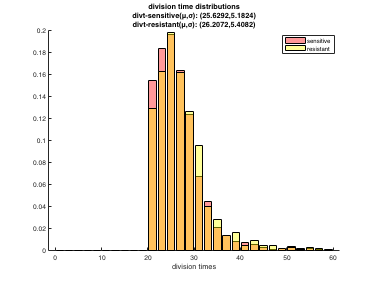


res = 2;
E = 0:res:60;
[sN,sedges] = histcounts(v_results.v_division_time(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(v_results.v_division_time(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off
xlabel("division times")
title(["division time distributions",...
    "divt-sensitive(μ,σ): ("+num2str(division_time_mean_sensitive)+","+...
    num2str(division_time_stdd_sensitive)+")", ...
    "divt-resistant(μ,σ): ("+num2str(division_time_mean_resistant)+","+...
    num2str(division_time_stdd_resistant)+")"])
legend(["sensitive","resistant"])

This difference enables the calculation of burden, the plasmid increases the division time of cells by:

percent_increase_in_division_time_wrt_sensitive_strain = num2str((resistant_minus_sensitive_division_time/division_time_mean_sensitive)*100) + "% with respect to the division time of the sensitive strain."

percent_increase_in_division_time_wrt_sensitive_strain = "2.2553% with respect to the division time of the sensitive strain."

## Lag time

CV = [];
END_LAG = [];
YFP = [];
for c=1:178
    log_area = log(data(c,:,2));
    yfp = mean(data(c,300:end,36));
    [lagt] = lagtime(0.05,log_area);
    END_LAG = [END_LAG,lagt(end)];
    YFP = [YFP, yfp];
end

When the mother machine experiment commences, the cells have been at stationary phase, centrifuged down to a high density and removed of most supernatant. As fresh growth media is flown into the mother machine, cells begin to wake up. The beauty of this experimental setup is the ability to observe cells throughout stationary, exponential and their eventual phase of decline.

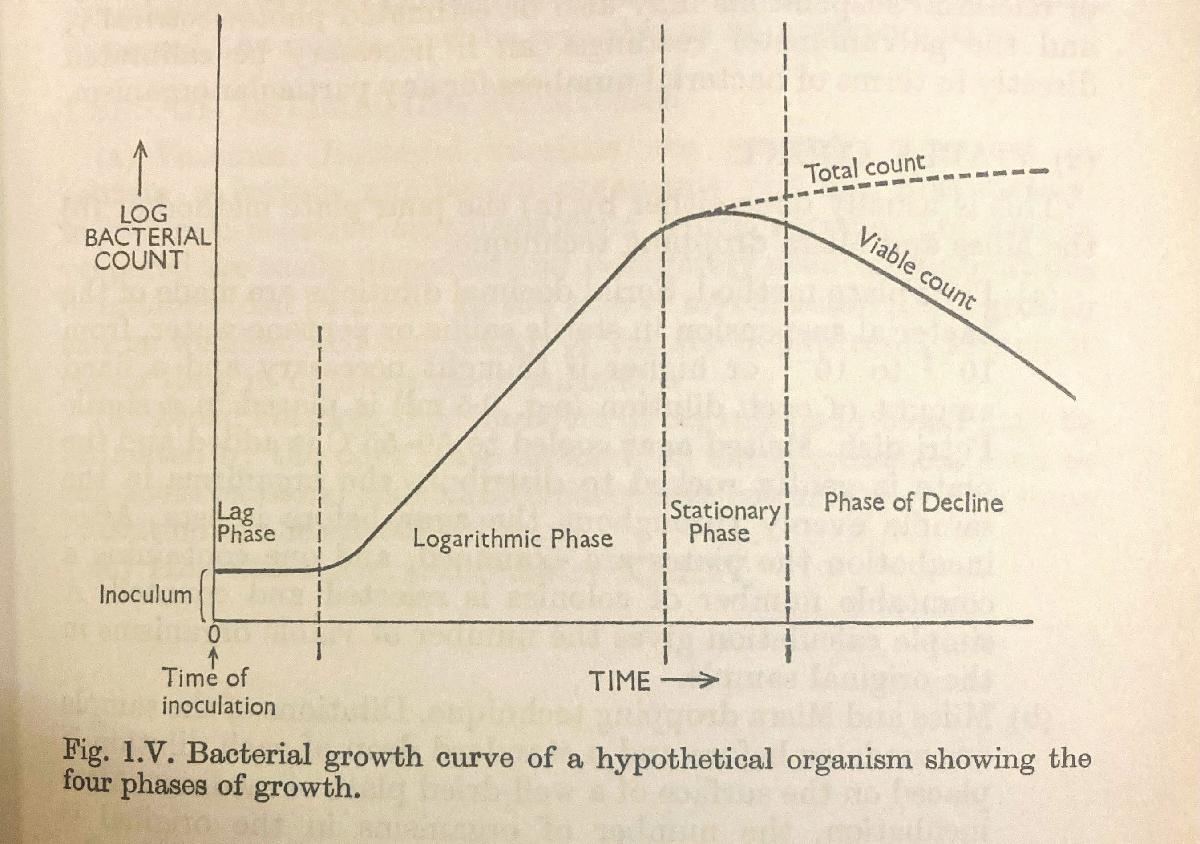

The lag time of a culture describes how far behind in time the culture is in it's growth profile in comparison to a culture that started at its optimal growth rate. This growth rate can be found by the equation: 


$$\textrm{lagtime}\left(t\right)=t-\frac{1}{\lambda_{\max } }\int_0^t \lambda_{\textrm{instantaneous}} \left(t\right)\textrm{dt}$$


*(Basan 2020)*

Below is a plot of lag time for a mother cell. Note the lag time eventually plateaus as the cell reaches exponential phase. Distributions of this final value are analysed to try and understand the effects of expressing the plasmid enabling resistance.

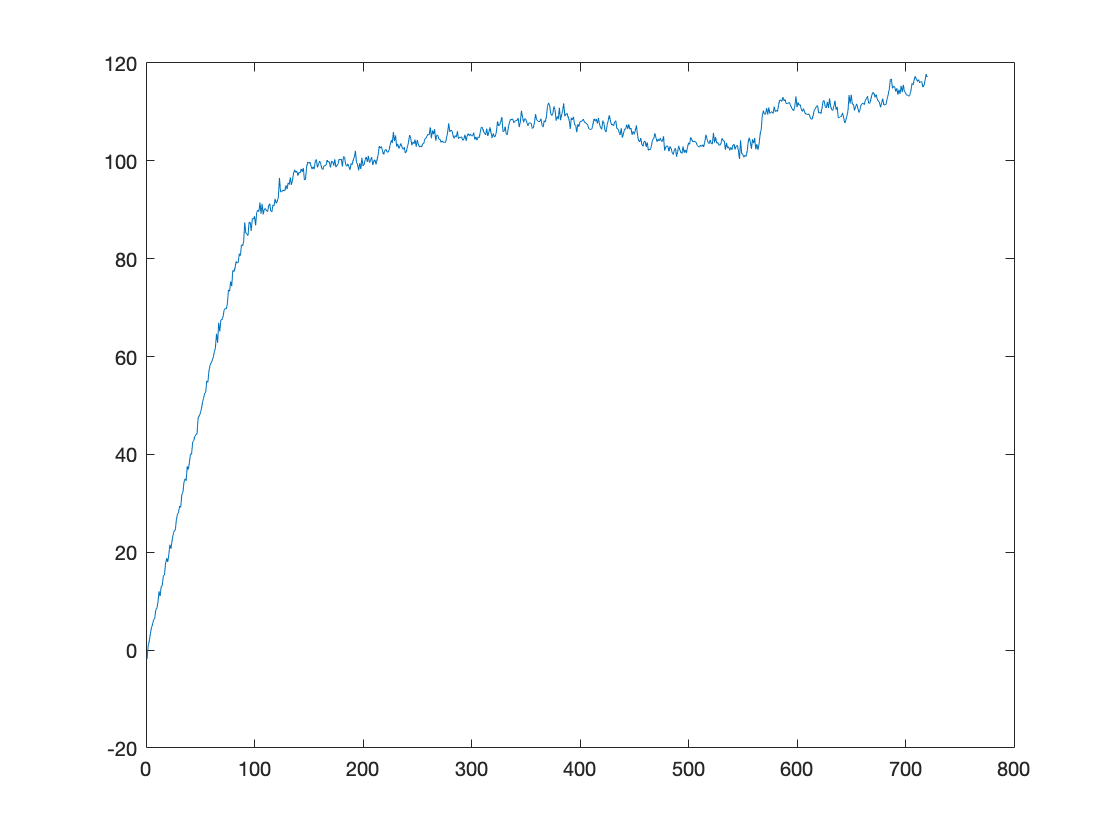

log_area = log(data(c,:,2));
[lagt] = lagtime(0.05,log_area);
plot(lagt)

First, the population of mother cells is segmented as was done for the lifetimes. Here, the population was segmented using YFP intensity data after 300 timepoints to account for the wake up of cells. Since we are not defracting lifetiimes for analysis as done above, this ensures that we correctly assign mother cells to the resistant and sensitive populations without effects due to wake up which occur in the initial timepoints of the experiment.

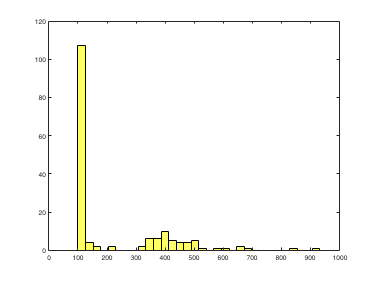

clf
histogram(YFP,150,'FaceColor','yellow')
xlim([0,1000])

Once again, the population can be segmented with a threshold of 250. 

The below histograms of final lag time demonstrate that resistant strains lag farther behind sensitive strains. This is anothe facet of fitness cost. If it takes resistant cells longer to reach exponential phase than sensitive cells, sensitive cells will be able to utilize more of the resources in the environment, and due to the exponentially nature of cell growth a head start will lead to an exponentially growing difference between the two population sizes over time. Even a slight increase in lag time to exponential phase can have a significant impact on fitness. Here, the resistant strains on average lag behind sensitive strains by:


lag_res = END_LAG(YFP > 250);
m_lag_res = mean(lag_res);
s_lag_res = std(lag_res);

lag_sens = END_LAG(YFP <= 250);
m_lag_sens = mean(lag_sens);
s_lag_sens = std(lag_sens);

difference_in_lag_time = num2str(m_lag_res-m_lag_sens)+ " minutes"

difference_in_lag_time = "21.978 minutes"

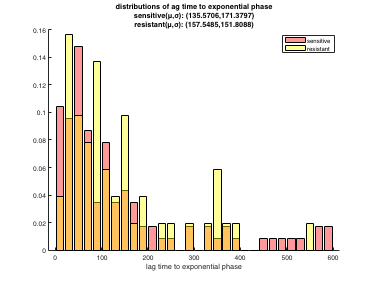


res = 20;
E = 0:res:600;
[sN,sedges] = histcounts(lag_sens,E,'Normalization','probability');
[rN,redges] = histcounts(lag_res,E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off

xlabel("lag time to exponential phase")
title(["distributions of ag time to exponential phase",...
    "sensitive(μ,σ): ("+num2str(m_lag_sens)+","+...
    num2str(s_lag_sens)+")", ...
    "resistant(μ,σ): ("+num2str(m_lag_res)+","+...
    num2str(s_lag_res)+")"])
legend(["sensitive","resistant"])

### Population Growth rate

The fitness of a culture is very much a factor of the population. This is particularly notable when considering a population of cells where growth rate is more noisy. Such a population will be fitter, since there will be some cells with a much higher growth rate due to the noise, and hence those will outperform the slower growing cells in the population and take up a much larger fraction of the culture's cell population.

The below figure illustrates this. Hashimoto et al 2016 ran a simulation where the division time of a cell lifetime is determined by the random roll of a dice. The effects of the first division are colored in the population tree depicted below. The first daughter cells from the seeded mother cell divided in different times, one in 5h and the other in 2h. All remaining cells still follow the same rule where their division time is determined by the role of a fair dice, however the lineage of the faster of the two first daughter cells will remain to be larger than the lineage formed by the slower one due to the exponential growth of these populations. To this regard a more noisy population will have a higher propensity to have faster to divide cell lifetimes occur earlier in the population tree.

 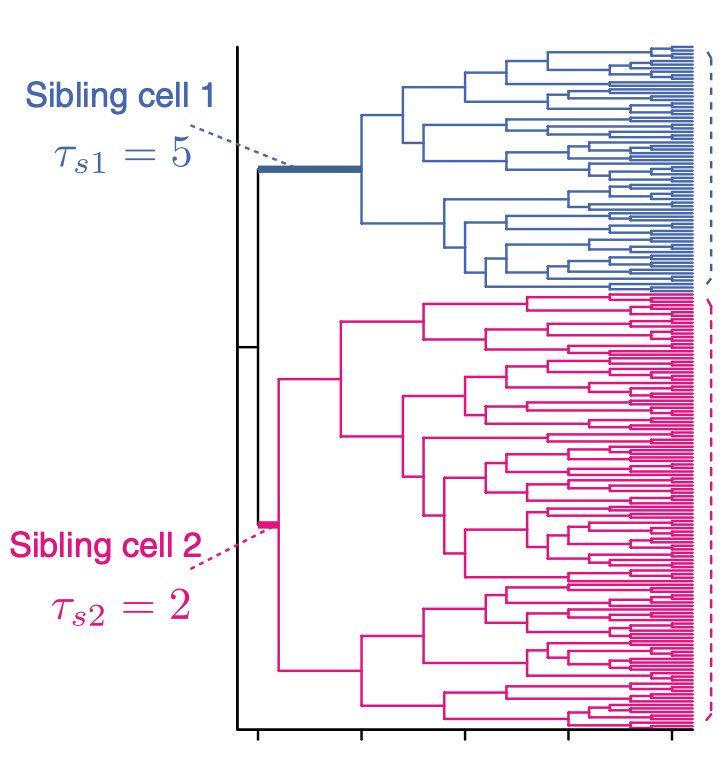

*(Adapted from Hashimoto 2016)*

Further simulations support the conclusion that higher noise increases the population growth rate. To this regard the distribution of growth rates from cell lifetimes in the mother machine doesn't reflect these properties of cells growing in a population.

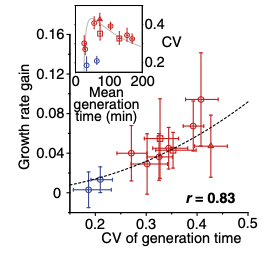

*(Adapted from Hashimoto 2016)*

Predictions for population growth rate calculated can be calculated for the lineage of each mother cell following the below equation from 

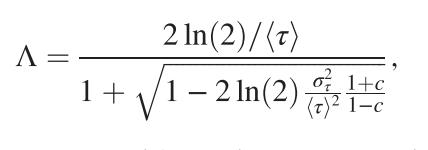

*(Leviein 2020)*

Here, $\langle \tau \rangle$ is the mean growth rate for lifetimes of a specific mother cell, $\sigma_{\tau }$ the standard deviation of those growth rates and $c$ the correlation between mother and daughter cell division times. Each division event for a cell can be assumed to be unbiased. The Hence identity of mother and daughter of the resulting two cells of a division event can be chosen at will. Hence, the mother cell at a timepoint in a mother machine side channel can infact be considered a daughter cell of the last mother cell in time in that side channel. Hence, the correlation between mother and daughter cell division times is simply the autocorrelation of the division times for the mother cell with a delay of 1 lfietime.

Due to the need for the mother daughter correlation times, the calculations for population fitness must be done at a mother cell lineage level rather than looking at all cell lifetimes disjointedly. The below image demonstrates the concept of a cell lineage: a direct path to the seed ansestor. In this experiment, a single cell at the back of the trench is retained and analysed whilst all other are washed away. Considering the concept of cell lineage, the whole lifetime of a mother cell imaged in the mother machine is a complete lineage. Given that the two strains were each grown from a colony on an agar pad seeded from a single ansestor, these mother cell trajectories are truncated trajectories of a strain's population tree. Note that since there are two strains in the experiment, there are two population trees - so the highlighted lineage below may be for example of two mother cells from the sensitive cell strain.

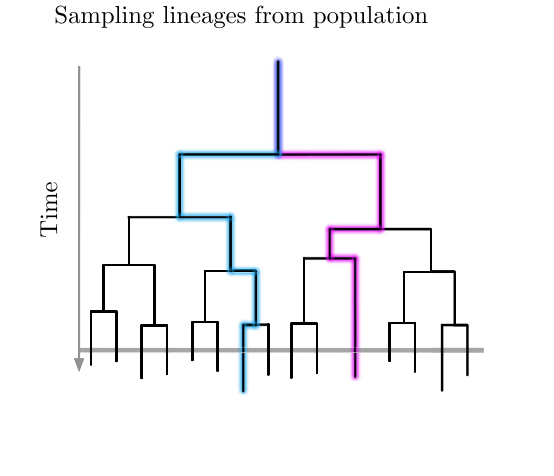

The below plots demonstrate the results of predicting population growth rates for sensitive and resistant cells respectively. The blue distributions are the distributions of the mean growth rates of lifetimes for a mother cell trajectory, and the red distributions are the distributions of predicted population growth rates found from mother cell trajectories.

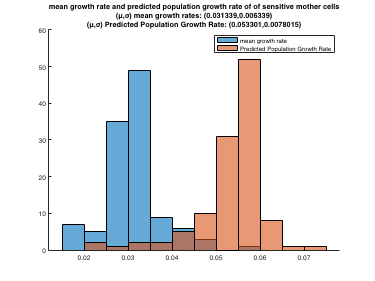

sens_gr_MM = [];
sens_gr_pop = [];
cell_id = 1:178;
for cell_num = cell_id(YFP <= 250)
    tau = results.division_time(cell_num,:);
    tau(tau==0) = [];
    
    
    moth_tau = tau(1:end-1);
    daug_tau = tau(2:end);
    c = mean((moth_tau-mean(moth_tau)) .* (daug_tau-mean(daug_tau)))/...
        (std(moth_tau)*std(daug_tau));
    
    p_gr = (2*log(2)/mean(tau))/...
                (...
                    1+sqrt(1-2*log(2)*...
                        (std(tau)/(mean(tau))^2) * ((1+c)/(1-c))...
                    ) ...
                );
    sens_gr_MM = [sens_gr_MM, mean(results.growth_rate(cell_num,:))];
    sens_gr_pop = [sens_gr_pop, p_gr];
end
clf
hold on
histogram(sens_gr_MM)
histogram(sens_gr_pop)
hold off
legend("mean growth rate","Predicted Population Growth Rate")
title(["mean growth rate and predicted population growth rate of of sensitive mother cells","(μ,σ) mean growth rates: ("+num2str(mean(sens_gr_MM))+","+num2str(std(sens_gr_MM))+")",...
    "(μ,σ) Predicted Population Growth Rate: ("+num2str(mean(sens_gr_pop))+","+num2str(std(sens_gr_pop))+")"])

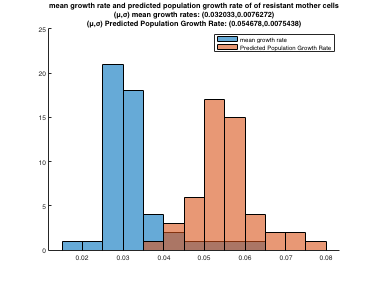


res_gr_MM = [];
res_gr_pop = [];
cell_id = 1:178;
for cell_num = cell_id(YFP > 250)
    tau = results.division_time(cell_num,:);
    tau(tau==0) = [];
    
    
    moth_tau = tau(1:end-1);
    daug_tau = tau(2:end);
    c = mean((moth_tau-mean(moth_tau)) .* (daug_tau-mean(daug_tau)))/...
        (std(moth_tau)*std(daug_tau));
    
    p_gr = (2*log(2)/mean(tau))/...
                (...
                    1+sqrt(1-2*log(2)*...
                        (std(tau)/(mean(tau))^2) * ((1+c)/(1-c))...
                    ) ...
                );
    res_gr_MM = [res_gr_MM, mean(results.growth_rate(cell_num,:))];
    res_gr_pop = [res_gr_pop, p_gr];
end
clf
hold on
histogram(res_gr_MM)
histogram(res_gr_pop)
hold off
legend("mean growth rate","Predicted Population Growth Rate")

title(["mean growth rate and predicted population growth rate of of resistant mother cells","(μ,σ) mean growth rates: ("+num2str(mean(res_gr_MM))+","+num2str(std(res_gr_MM))+")",...
    "(μ,σ) Predicted Population Growth Rate: ("+num2str(mean(res_gr_pop))+","+num2str(std(res_gr_pop))+")"])

The mean estimated population growth rates can be used to predict the burden of the plasmid enabling resistance as done from the division time distributions:

"percent_increase_in_division_time_wrt_sensitive_strain_using_population_growth_rate_perdiction "+...
    num2str(((mean(res_gr_pop)-mean(sens_gr_pop))/mean(sens_gr_pop))*100)...
+ "% with respect to the predicted population growth rate of the sensitive strain."

ans = "percent_increase_in_division_time_wrt_sensitive_strain_using_population_growth_rate_perdiction 2.5824% with respect to the predicted population growth rate of the sensitive strain."